# Ch 15 - Nonlinear Regression

## Book Method

 v = [1 2 3 4 5];
 F = [2.1 4.5 7.9 12.6 19.3];

 a_guess = [1 1];
 a = fminsearch(@fSSR, a_guess, [], v, F)

a =     1.3505    1.6404


## Book Method 2

x = [1 2 3 4 5]';
y = [2.1 4.5 7.9 12.6 19.3]';

Z = [ones(size(x)) x x.^2 x.^3];
a = (Z'*Z)\(Z'*y)

a =     0.0800
    1.9738
   -0.0429
    0.0833


Sr = sum((y-Z*a).^2)

Sr = 0.0023

r2 = 1-Sr/sum((y-mean(y)).^2)

r2 = 1.0000


% go down the column vector
0.08 + 1.97*x - 0.0429*x.^2 + 0.0833*x.^3

ans =     2.0904
    4.5148
    7.8530
   12.6048
   19.2700


## Built-In Method

% fitnlm
 v = [1 2 3 4 5];
 F = [2.1 4.5 7.9 12.6 19.3];

% Define model: F = a1 * v^a2
modelfun = @(b,x) b(1) * x.^b(2);

beta0 = [1 1];
nlm = fitnlm(v,F,modelfun,beta0)

nlm = Nonlinear regression model:
    y ~ b1*x^b2

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________

    b1     1.3505     0.21788    6.1986     0.0084592
    b2     1.6404     0.10913    15.031    0.00063916


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.617
R-Squared: 0.994,  Adjusted R-Squared 0.992
F-statistic vs. zero model: 809, p-value = 7.95e-05


% isqcurvefit
model = @(b,x) b(1) * x.^b(2);
b0 = [1 1];
a_fit = lsqcurvefit(model,b0,v,F)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


a_fit =     1.3505    1.6404


## Ch14 Nonlin Transform Again

x = [0.1 0.2 0.4 0.6 0.9 1.3 1.5 1.7 1.8];
y = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18];

% y = alph4*x*exp(beta4*x) % fit it to that model

a = fminsearch(@fSSR, [1 1], [], x, y)

a =     9.8974   -2.5319



n = length(x);
if length(y)~=n, error('x and y must be same length'); end
x = x(:); y = y(:); % convert to column vectors
sx = sum(x); sy = sum(y);
sx2 = sum(x.*x); sxy = sum(x.*y); sy2 = sum(y.*y);
a(1) = (n*sxy-sx*sy)/(n*sx2-sx^2);
a(2) = sy/n-a(1)*sx/n;
r2 = ((n*sxy-sx*sy)/sqrt(n*sx2-sx^2)/sqrt(n*sy2-sy^2))^2

r2 = 0.7157

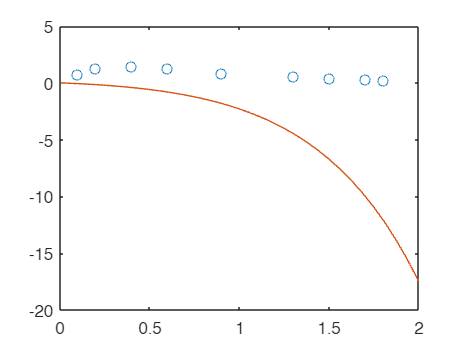


xp = [0:2/32:2];
yp = a(1)*xp.*exp(a(2)*xp);
plot(x,y,'o',xp,yp)
hold off;